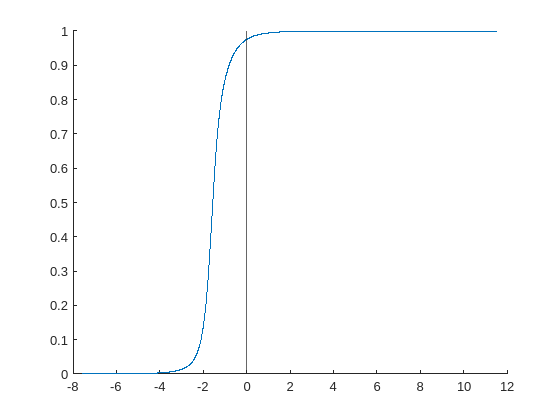

KAon = 10.0;
KAoff = 10.0;
KIon = 10.0;
KIoff = 10.0;
KIcat = 10.0;
KAcat = 100.0;


% Ptot = 10.0;
% Ktot = 10.0;

Tot = 100;
tots = 0.001:0.05:Tot;
ss = zeros(4, length(tots));
ratios = zeros(2, length(tots));
for i = 1:length(tots)
    x = tots(i);
    Ptot = x;
    Ktot = Tot - x;
    ratios(1, i) = log(Ktot/Ptot);
    ratios(2, i) = Ktot / (Ktot + Ptot);

    dAdt  = @(A, I, AP, IK) -KAon*A*(Ptot-AP) + KAoff*AP + KAcat*IK;
    dIdt  = @(A, I, AP, IK) -KIon*I*(Ktot-IK) + KIoff*IK + KIcat*AP;
    dAPdt = @(A, I, AP, IK) KAon*A*(Ptot-AP) - KAoff*AP - KIcat*AP;
    dIKdt = @(A, I, AP, IK) -KIoff*IK + KIon*I*(Ktot-IK) - KAcat*IK;
    
    [T, X] = ode45(@(t,x)[ ...
        dAdt(x(1), x(2), x(3), x(4)); ...
        dIdt(x(1), x(2), x(3), x(4)); ...
        dAPdt(x(1), x(2), x(3), x(4)); ...
        dIKdt(x(1), x(2), x(3), x(4))], ...
        [0.0,0.1], [0.0,100.0,0.0,0.0]);
    ss(1, i) = X(end, 1) / (X(end, 1) + X(end, 2));
end
% ratios
figure(1);
hold on;
plot(ratios(1,:), ss(1,:));
xline(0);
hold off;

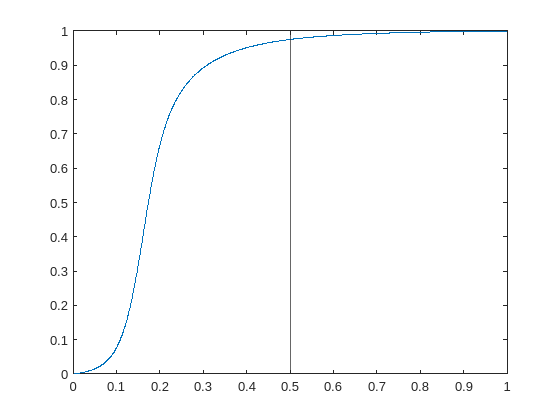


figure(2);
% hold on;
plot(ratios(2,:), ss(1,:));
xline(0.5);

% hold off;
% plot(ratios, ss(2,:))
% plot(ratios, ss(3,:))
% plot(ratios, ss(4,:))
% legend("A", "I", "AP", "IK")
% hold off;
% plot()
% plot(T, X);
% legend("A", "I", "AP", "IK")